clear, clc

## LOAD ASHBY

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Ashby';
mvcs = 7;
for i = 1:mvcs
    name = [num2str(i*10) '_MVC'];
    data(i) = load([path '\' name '.mat']);
end
clear path, clear names, clear i

## LOAD ERRORS

path = 'D:\University programming\MATLAB\Module 12\Neuron Parameter Estimation\Errors';
mvcs = 7;
for i = 1:mvcs
    name = [num2str(i*10) '_MVC'];
    data_e(i) = load([path '\' name '.mat']);
end
clear path, clear names, clear i

## PLOT ASHBY

figure, clf, hold on
for mvc = 1:mvcs
    clusters = size(data(mvc).Ashby,1);
    col = rand(1,3);
    for clus = 1:clusters
        x = data(mvc).Ashby{clus,1};
        y = data(mvc).Ashby{clus,2};
        h(mvc) = fill(x,y,col,'LineStyle','none','FaceAlpha',0.5);
    end
    lg_names{mvc} = [num2str(mvc*10) '% MVC'];
end
xlabel('dSoma')
ylabel('betaQ')
legend(h,lg_names,'Location','eastoutside')
xlim([40,135])
ylim([0.01,0.2])

set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 1]);

## PLOT ONE PARAMETER AGIST THE OTHER

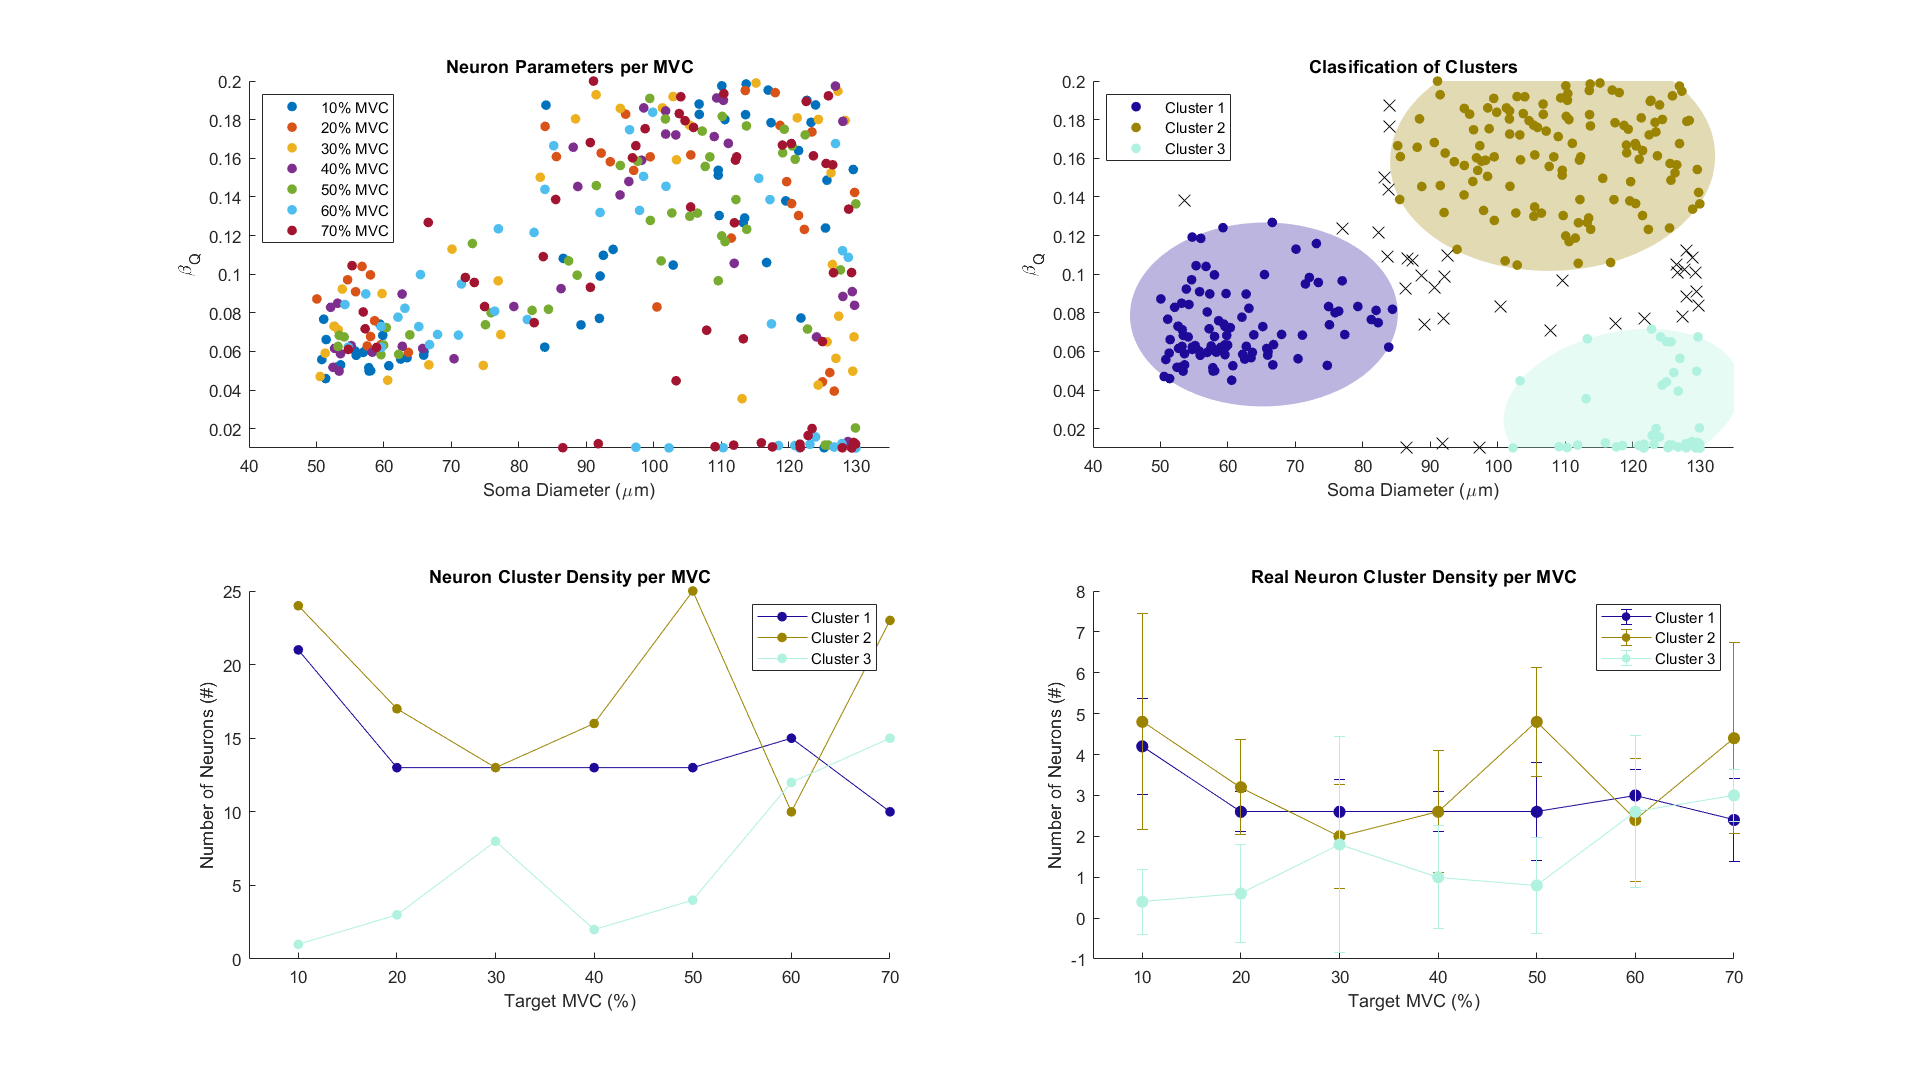

for i = 1:mvcs
    n_points(i) = length(data(i).X(:,1));
end
X_dSoma = NaN(max(n_points),mvcs);
X_betaQ = NaN(max(n_points),mvcs);
figure, clf
% Plot 1
subplot(2,2,1), hold on
for i = 1:mvcs
    plot(data(i).X(:,1),data(i).X(:,2),'.','MarkerSize',20)
    X_dSoma(1:length(data(i).X(:,1)),i) = data(i).X(:,1);
    X_betaQ(1:length(data(i).X(:,2)),i) = data(i).X(:,2);
    lg_names3{i} = [num2str(i*10) '% MVC '];
end
legend(lg_names3,'Location','northwest')
xlabel('Soma Diameter (\mum)')
ylabel('\beta_{Q}')
xlim([40,135])
ylim([0.01,0.2])
title('Neuron Parameters per MVC')

X1 = reshape(X_dSoma,[],1); X2 = reshape(X_betaQ,[],1);
X1 = X1(~isnan(X1)); X2 = X2(~isnan(X2));
X = [X1,X2];
X_nor = normalize(X,'range');

% Plot 2
subplot(2,2,2), hold on
clusters = 3;
start = [0.1,0.4;
    0.8,0.8;
    0.9,0.1];
[idx,Centroids] = kmeans(X_nor,clusters,'Distance','cityblock','Start',start);
Distances = sqrt(sum((X_nor - Centroids(idx,:)).^2,2));
InC = Distances <= 3*std(Distances);
Ashby = cell(clusters,2);
for clus = 1:clusters
    color(clus,[1 2 3]) = rand(1,3);
    h_clus(clus) = plot(X(idx==clus & InC==1,1),X(idx==clus & InC==1,2),'.','MarkerSize',20,'Color',color(clus,:));
    lg_names{clus} = ['Cluster ' num2str(clus)];
    [A,c] = MinVolEllipse([X(idx==clus & InC==1,1)';X(idx==clus & InC==1,2)'],0.001);
    [U,Q,V] = svd(A);
    [x,y] = Functions.Ellipse(c,Q,V(2,2));
    fill(x,y,color(clus,:),'LineStyle','none','FaceAlpha',0.3)
    Ashby{clus,1} = x;
    Ashby{clus,2} = y;
end
plot(X(~InC,1),X(~InC,2),'x','MarkerSize',10,'Color',[15 15 15]/255);
% plot(Centroids(:,1),Centroids(:,2),'kx','MarkerSize',15,'LineWidth',3)
xlabel('Soma Diameter (\mum)')
ylabel('\beta_{Q}')
legend(h_clus,lg_names,'Location','northwest')
xlim([40,135])
ylim([0.01,0.2])
title('Clasification of Clusters')

forStart = 1;
forEnd = 0;
for i = 1:mvcs
    forEnd = forEnd + n_points(i);
    DensityClus(i,[1,2,3]) = [sum(idx(forStart:forEnd)==1 & InC(forStart:forEnd)==1),...
        sum(idx(forStart:forEnd)==2 & InC(forStart:forEnd)==1),sum(idx(forStart:forEnd)==3 & InC(forStart:forEnd)==1)];
    forStart = forStart + n_points(i);
end

% Plot 3
subplot(2,2,3), hold on
for clus = 1:clusters
    plot(DensityClus(:,clus),'.-','MarkerSize',20,'Color',color(clus,:))
end
xticks(0:mvcs)
xticklabels({'','10','20','30','40','50','60','70'})
xlim([0.5,7])
xlabel('Target MVC (%)')
ylabel('Number of Neurons (#)')
legend(lg_names,'Location','northeast')
title('Neuron Cluster Density per MVC')

% Plot 4
subplot(2,2,4), hold on
for i = 1:mvcs
    meanDC(i,:) = mean(data(i).DensityClus,1);
    stdDC(i,:) = std(data(i).DensityClus,1);
end
for i = 1:clusters
    errorbar(meanDC(:,i),stdDC(:,i),'.-','MarkerSize',25,'Color',color(i,:))
end
xticks(0:mvcs)
xticklabels({'','10','20','30','40','50','60','70'})
xlim([0.5,7])
xlabel('Target MVC (%)')
ylabel('Number of Neurons (#)')
legend(lg_names,'Location','northeast')
title('Real Neuron Cluster Density per MVC')

set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 1]);

## FINAL PLOT

for i = 1:mvcs
    n_points(i) = length(data(i).X(:,1));
end
X_dSoma = NaN(max(n_points),mvcs);
X_betaQ = NaN(max(n_points),mvcs);
for i = 1:mvcs
    X_dSoma(1:length(data(i).X(:,1)),i) = data(i).X(:,1);
    X_betaQ(1:length(data(i).X(:,2)),i) = data(i).X(:,2);
end
X1 = reshape(X_dSoma,[],1); X2 = reshape(X_betaQ,[],1);
X1 = X1(~isnan(X1)); X2 = X2(~isnan(X2));
X = [X1,X2];
X_nor = normalize(X,'range');

figure, clf
% Plot 1
subplot(2,2,1), hold on
col = [0.4116    0.6026    0.7505;
    0.5835    0.5518    0.5836;
    0.5118    0.0826    0.7196;
    0.9962    0.3545    0.9713;
    0.3464    0.8865    0.4547;
    0.4134    0.2177    0.1257;
    0.3089    0.7261    0.7829];
for mvc = 1:mvcs
    clusters = size(data(mvc).Ashby,1);
%     col(mvc,1:3) = rand(1,3);
    for clus = 1:clusters
        x = data(mvc).Ashby{clus,1};
        y = data(mvc).Ashby{clus,2};
        h(mvc) = fill(x,y,col(mvc,1:3),'LineStyle','none','FaceAlpha',0.5);
    end
    lg_names{mvc} = [num2str(mvc*10) '% MVC'];
end
xlabel('Soma Diameter (\mum)')
ylabel('\beta_{Q} (ms^{-1})')
legend(h,lg_names,'Location','northwest')
xlim([40,135])
ylim([0.01,0.2])
title('Cluster Similitude')

% Plot 2
subplot(2,2,3), hold on
clusters = 3;
start = [0.1,0.4;
    0.8,0.8;
    0.9,0.1];
[idx,Centroids] = kmeans(X_nor,clusters,'Distance','cityblock','Start',start);
Distances = sqrt(sum((X_nor - Centroids(idx,:)).^2,2));
InC = Distances <= 3*std(Distances);
Ashby = cell(clusters,2);
color = [0.4299 0.8878 0.3912;
    0.7691 0.3968 0.8085;
    0.7551 0.3774 0.2160];
for clus = 1:clusters
%     color(clus,[1 2 3]) = rand(1,3);
    h_clus(clus) = plot(X(idx==clus & InC==1,1),X(idx==clus & InC==1,2),'.','MarkerSize',20,'Color',color(clus,:));
    lg_names{clus} = ['Cluster ' num2str(clus)];
    [A,c] = MinVolEllipse([X(idx==clus & InC==1,1)';X(idx==clus & InC==1,2)'],0.001);
    [U,Q,V] = svd(A);
    [x,y] = Functions.Ellipse(c,Q,V(2,2));
    fill(x,y,color(clus,:),'LineStyle','none','FaceAlpha',0.3)
    Ashby{clus,1} = x;
    Ashby{clus,2} = y;
end
plot(X(~InC,1),X(~InC,2),'x','MarkerSize',10,'Color',[15 15 15]/255);
% plot(Centroids(:,1),Centroids(:,2),'kx','MarkerSize',15,'LineWidth',3)
xlabel('Soma Diameter (\mum)')
ylabel('\beta_{Q} (ms^{-1})')
legend(h_clus,lg_names,'Location','northwest')

xlim([40,135])
ylim([0.01,0.2])
title('Generalized Clusters Clasification')

forStart = 1;
forEnd = 0;
for i = 1:mvcs
    forEnd = forEnd + n_points(i);
    DensityClus(i,[1,2,3]) = [sum(idx(forStart:forEnd)==1 & InC(forStart:forEnd)==1),...
        sum(idx(forStart:forEnd)==2 & InC(forStart:forEnd)==1),sum(idx(forStart:forEnd)==3 & InC(forStart:forEnd)==1)];
    forStart = forStart + n_points(i);
end

% Plot 3
subplot(2,2,4), hold on
for clus = 1:clusters
    plot(DensityClus(:,clus),'.-','MarkerSize',25,'Color',color(clus,:))
end
xticks(0:mvcs)
xticklabels({'','10','20','30','40','50','60','70'})
xlim([0.5,7])
ylim([0 30])
xlabel('Target MVC (%)')
ylabel('Number of Neurons (#)')
legend(lg_names,'Location','north')

title('Generalized Neuron Cluster Population')
% for i = 1:mvcs
%     for j = 1:4
%         errors_trial_mean(j,i) = mean(data_e(i).errors_trial_mean(j,:));
%         errors_trial_std(j,i) = std(data_e(i).errors_trial_mean(j,:));
%     end
% end
% for j = 1:4
%     errorbar(errors_trial_mean(j,:),errors_trial_std(j,:),'.-','MarkerSize',20)
% end
% xticks(0:mvcs)
% xticklabels({'','10','20','30','40','50','60','70'})
% xlim([0.5,mvcs+0.5])
% xlabel('Target MVC (%)')
% ylabel('Error Value (#)')
% ylim([0,1.4])
% legend({'Coincidence Factor','Mean Firing Rate','First Spike Time','Number of Spikes'},'Location','north')
% title('Error Funtions')

% Plot 4
subplot(2,2,2), hold on
for i = 1:mvcs
    meanDC(i,:) = mean(data(i).DensityClus,1);
    stdDC(i,:) = std(data(i).DensityClus,1);
end
for i = 1:clusters
    errorbar(meanDC(:,i),stdDC(:,i),'.-','MarkerSize',25,'Color',color(i,:))
end
xticks(0:mvcs)
xticklabels({'','10','20','30','40','50','60','70'})
xlim([0.5,7])
ylim([0 8])
xlabel('Target MVC (%)')
ylabel('Number of Neurons (#)')
legend(lg_names,'Location','north')

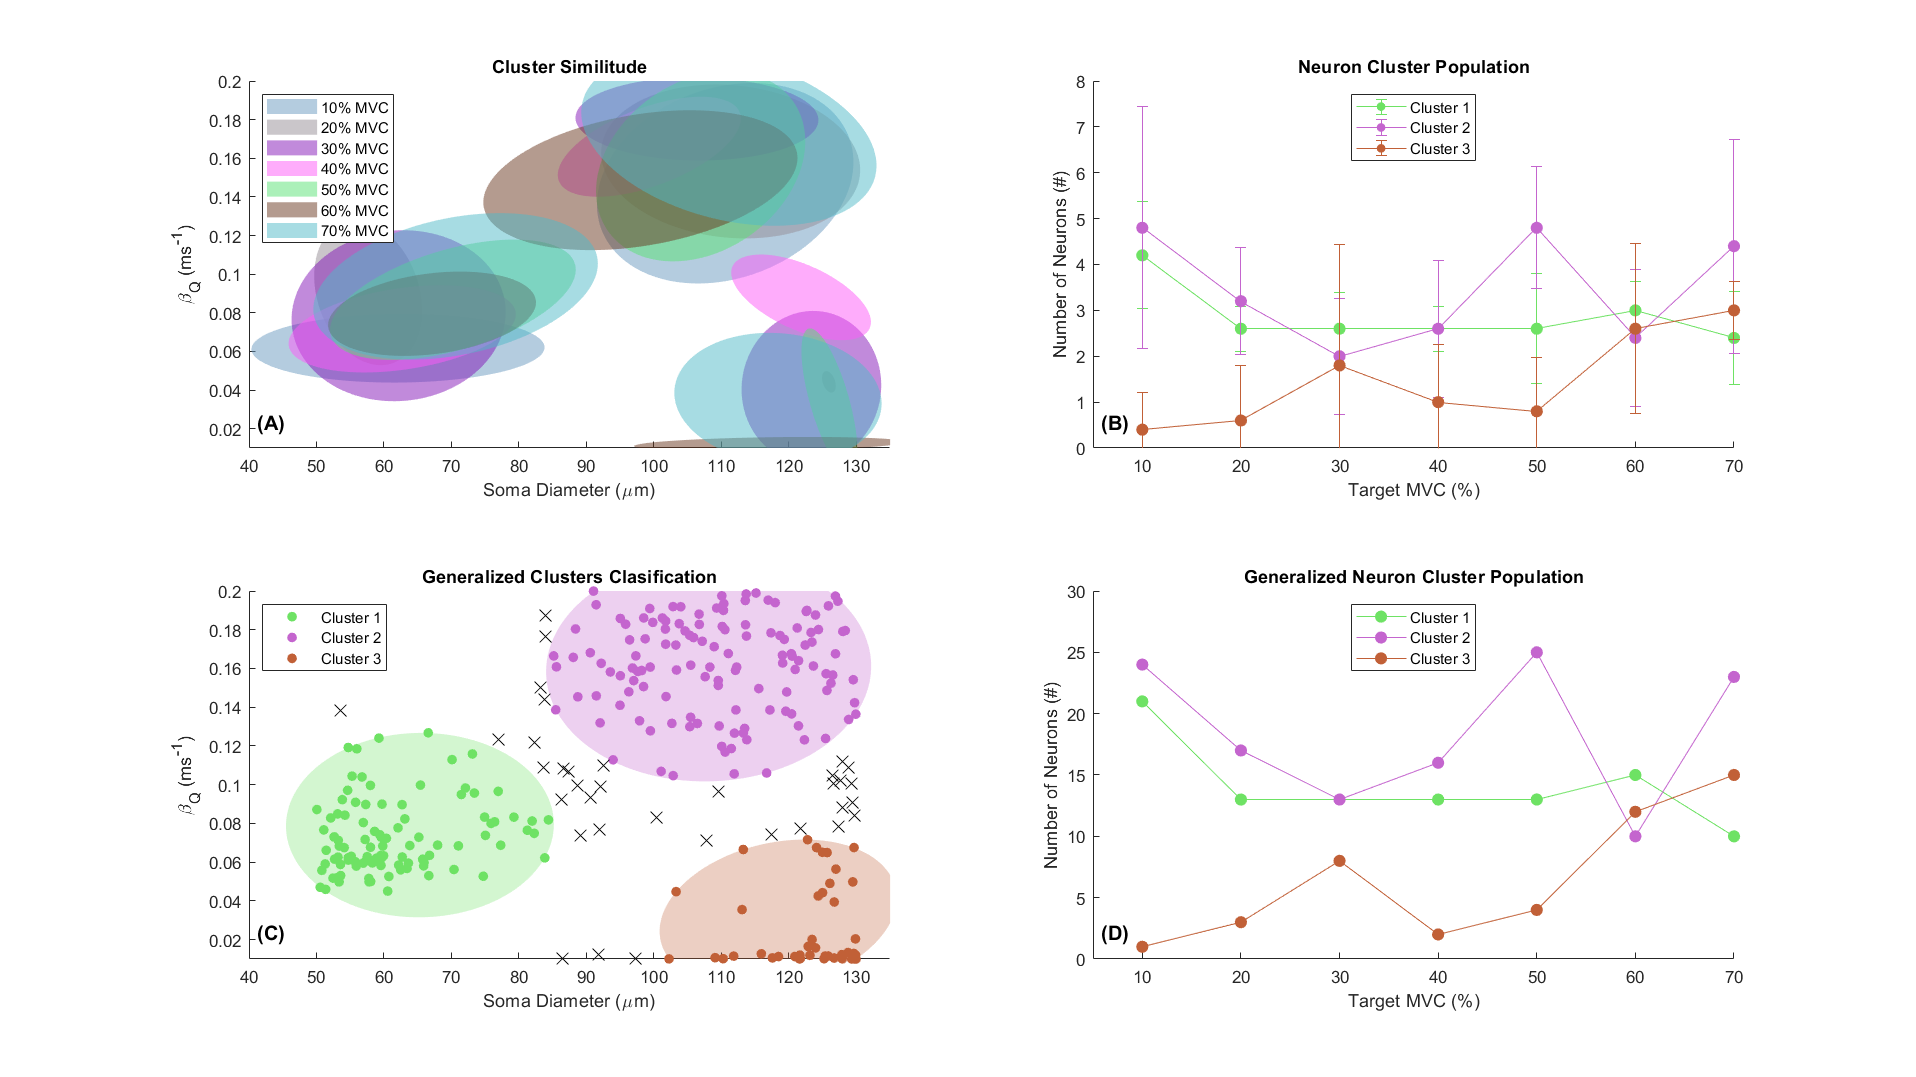

title('Neuron Cluster Population')

set(gcf, 'units', 'normalized');
set(gcf, 'Position', [0, 0, 1, 1]);
AddLetters2Plots(gcf, 'HShift', 0, 'VShift', 0.3, 'Direction', 'LeftRight')